Equipo:

- García Muñoz Ari Manuel 

- Morales Flores Pedro Martín 

- Pérez Medina Rafael 

- Pineda Marin Ulises 

- Salazar Garcia Daniel 

## E4.11

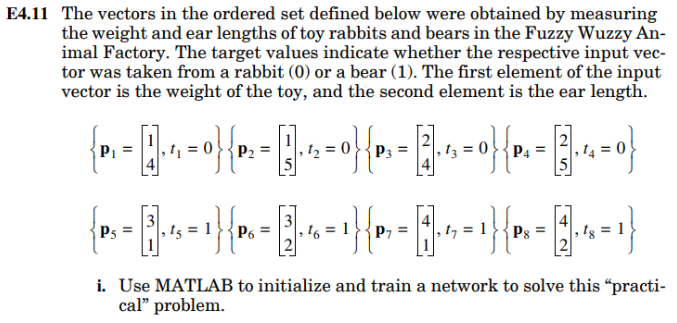

p1 = [1;4];t1=0;
p2 = [1;5];t2=0;
p3 = [2;4];t3=0;
p4 = [2;5];t4=0;
p5 = [3;1];t5=1;
p6 = [3;2];t6=1;
p7 = [4;1];t7=1;
p8 = [4;2];t8=1;
W0=[0 0]; b0= 0;
P=[p1 p2 p3 p4 p5 p6 p7 p8];
t=[t1 t2 t3 t4 t5 t6 t7 t8];
Iteraciones=[W0'; b0];
n=1;
br=0;
while br==0
    nueva = zeros(3,length(P));
    for i=1:length(P)
        [W,b] = algo_per_ite(W0,b0,P(1:2,i),t(1,i));
        W0=W;
        b0=b;
        Iteraciones = [Iteraciones [W0';b0]];
        nueva(1:3,i) = [W0';b0];
    end
    disp(Iteraciones);
    fprintf("Se termina la época %d",n);
    u=0;
    for i=1:length(nueva)-1
        if nueva(1:3,i)==nueva(1:3,i+1)
            u=u+1;
        end
    end
    if u==(length(nueva)-1)
        br=1;
    end
    n=n+1;
end

     0    -1    -1    -1    -1     2     2     2     2
     0    -4    -4    -4    -4    -3    -3    -3    -3
     0    -1    -1    -1    -1     0     0     0     0


Se termina la época 1

  Columns 1 through 16
     0    -1    -1    -1    -1     2     2     2     2     2     2     2     2     2     2     2
     0    -4    -4    -4    -4    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3
     0    -1    -1    -1    -1     0     0     0     0     0     0     0     0     0     0     0
  Column 17
     2
    -3
     0


Se termina la época 2

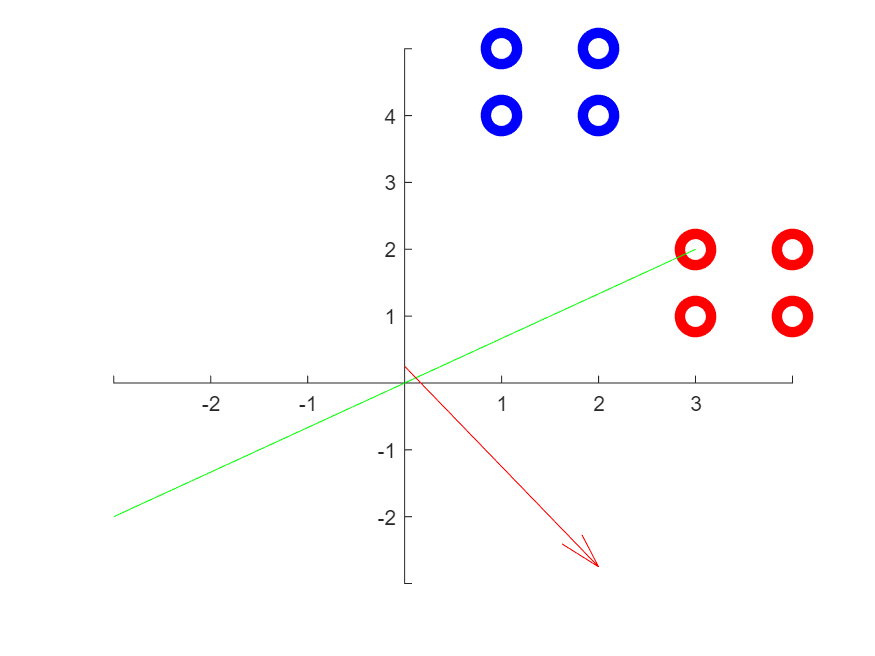

figure;
plot(P(1,1:4),P(2,1:4), 'ob','MarkerSize',15, 'LineWidth',5)
hold on 
plot(P(1,5:8),P(2,5:8),'or','MarkerSize',15, 'LineWidth',5)
g = gca;
g.XAxisLocation = 'origin';
g.YAxisLocation = 'origin';
g.Box = 'off';
fimplicit(@(p1,p2) W(1,1)*p1 + W(1,2)*p2 + b,[-3,3],'g')
quiver(0,.25,W(1,1),W(1,2),0, 'MaxHeadSize',0.5,"Color",'r','DisplayName',"_1w")

W0=W; b0= b;
p=[p1 p2 p3 p4 p5 p6 p7 p8];
t=[t1 t2 t3 t4 t5 t6 t7 t8];
Iteraciones=[W0'; b0];
n=1;
br=0;
while br==0
    nueva = zeros(3,length(p));
    for i=1:length(p)
        [W,b] = algo_per_ite(W0,b0,p(1:2,i),t(1,i));
        W0=W;
        b0=b;
        Iteraciones = [Iteraciones [W0';b0]];
        nueva(1:3,i) = [W0';b0];
    end
    disp(Iteraciones);
    fprintf("Se termina la época %d",n);
    u=0;
    for i=1:length(nueva)-1
        if nueva(1:3,i)==nueva(1:3,i+1)
            u=u+1;
        end
    end
    if u==(length(nueva)-1)
        br=1;
    end
    n=n+1;
end

     2     2     2     2     2     2     2     2     2
    -3    -3    -3    -3    -3    -3    -3    -3    -3
     0     0     0     0     0     0     0     0     0


Se termina la época 1

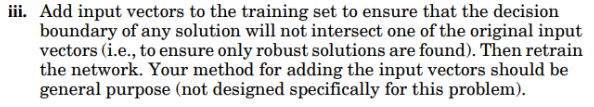

Se le agregaron 2 entradas en los vectores P2 y t2 que concatenan las anteriores entradas con 2 nuevas(una de cada tipo)

pn1 = [1.5;3]; tn1 = 0;
pn2 = [2;1.5]; tn2 = 1;

P2=[P, pn1, pn2];
t2=[t, tn1, tn2];
W0=[0 0]; b0= 0;
Iteraciones=[W0'; b0];
n=1;
br=0;
while br==0
    nueva = zeros(3,length(P2));
    for i=1:length(P2)
        [W,b] = algo_per_ite(W0,b0,P2(1:2,i),t2(1,i));
        W0=W;
        b0=b;
        Iteraciones = [Iteraciones [W0';b0]];
        nueva(1:3,i) = [W0';b0];
    end
    disp(Iteraciones);
    fprintf("Se termina la época %d",n);
    u=0;
    for i=1:length(nueva)-1
        if nueva(1:3,i)==nueva(1:3,i+1)
            u=u+1;
        end
    end
    if u==(length(nueva)-1)
        br=1;
    end
    n=n+1;
end

  Columns 1 through 9
         0   -1.0000   -1.0000   -1.0000   -1.0000    2.0000    2.0000    2.0000    2.0000
         0   -4.0000   -4.0000   -4.0000   -4.0000   -3.0000   -3.0000   -3.0000   -3.0000
         0   -1.0000   -1.0000   -1.0000   -1.0000         0         0         0         0
  Columns 10 through 11
    2.0000    4.0000
   -3.0000   -1.5000
         0    1.0000


Se termina la época 1

  Columns 1 through 9
         0   -1.0000   -1.0000   -1.0000   -1.0000    2.0000    2.0000    2.0000    2.0000
         0   -4.0000   -4.0000   -4.0000   -4.0000   -3.0000   -3.0000   -3.0000   -3.0000
         0   -1.0000   -1.0000   -1.0000   -1.0000         0         0         0         0
  Columns 10 through 18
    2.0000    4.0000    4.0000    4.0000    2.0000    2.0000    2.0000    5.0000    5.0000
   -3.0000   -1.5000   -1.5000   -1.5000   -5.5000   -5.5000   -5.5000   -3.5000   -3.5000
         0    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000
  Columns 19 through 21
    5.0000    5.0000    5.0000
   -3.5000   -3.5000   -3.5000
    1.0000    1.0000    1.0000


Se termina la época 2

  Columns 1 through 9
         0   -1.0000   -1.0000   -1.0000   -1.0000    2.0000    2.0000    2.0000    2.0000
         0   -4.0000   -4.0000   -4.0000   -4.0000   -3.0000   -3.0000   -3.0000   -3.0000
         0   -1.0000   -1.0000   -1.0000   -1.0000         0         0         0         0
  Columns 10 through 18
    2.0000    4.0000    4.0000    4.0000    2.0000    2.0000    2.0000    5.0000    5.0000
   -3.0000   -1.5000   -1.5000   -1.5000   -5.5000   -5.5000   -5.5000   -3.5000   -3.5000
         0    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000
  Columns 19 through 27
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
  Columns 28 through 31
    5.0000    5.0000    5.0000    5.0000
   -3.5000   -3.5000   -3.5000   -3.5000
    1

Se termina la época 3

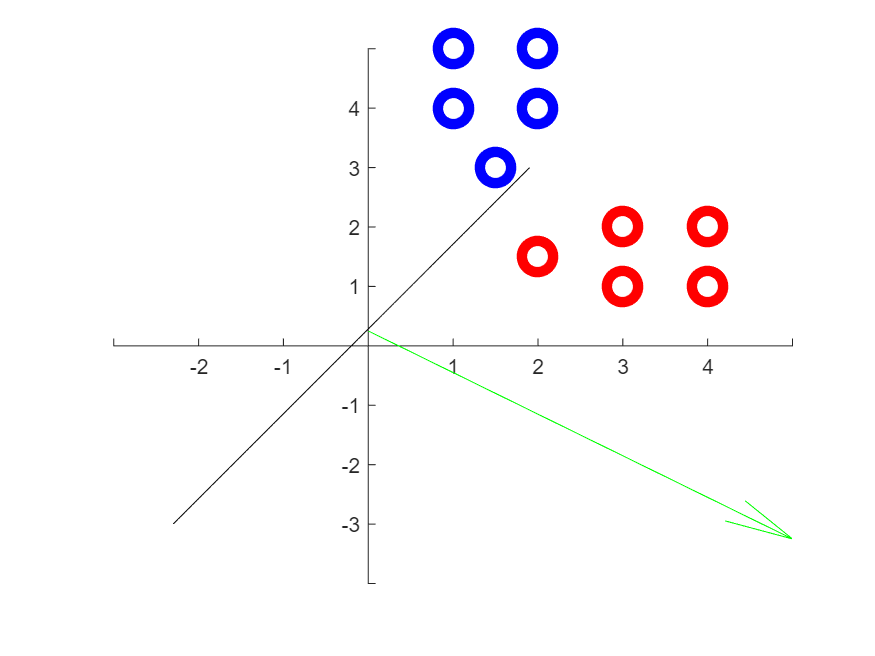

figure;
plot(P2(1,[1:4]),P2(2,1:4), 'ob','MarkerSize',15, 'LineWidth',5)
hold on 
plot(P2(1,9),P2(2,9), 'ob','MarkerSize',15, 'LineWidth',5)
plot(P2(1,5:8),P2(2,5:8),'or','MarkerSize',15, 'LineWidth',5)
plot(P2(1,10),P2(2,10), 'or','MarkerSize',15, 'LineWidth',5)
g = gca;
g.XAxisLocation = 'origin';
g.YAxisLocation = 'origin';
g.Box = 'off';
fimplicit(@(p1,p2) W(1,1)*p1 + W(1,2)*p2 + b,[-3,3],'k')
quiver(0,.25,W(1,1),W(1,2),0, 'MaxHeadSize',0.5,"Color",'g','DisplayName',"_1w")

function [W,b] = algo_per_ite(W0,b0,p,t)
a = hardlim(W0 * p + b0);
e = t - a;
W = W0  +  e * p';
b = b0 +  e;
end